% Filtro IIR Butterworth - Pasa alto
% filipuzzi, fernando rafael
% fecha: 20221024
% matlab2021b

close all; clear all; clc;
digits(300);
addpath ./embedded
addpath ./mifiltertools
addpath ./utils
format LONGE

**Filtro - IIR - Diseño del filtro Pasa Alto**

**Parámetros de diseño**

fm=22418;             % Hz,  Frecuencia de Muestreo
fMAX=fm/2;
                           fc=1000;
fs=750 ;                    fp=1250 ;               
As=15 ;                     Ap=0.3 ;                                
                        

**Diseño del filtro**

- Transformar las caracteristicas de frecuencia de paso alto a paso bajo normalizado

Fc=1;
Fs=fp/fc;
Fp=fp/fc;

- Cálculo del Orden del filtro:

N=mi_butter_orden_lp(Fp, Ap, Fs, As)

N =      8


- Función de transferencia y respuesta en frecuencia

[BS,AS]=mi_butter(N);
sysS=tf(BS,AS)

sysS =
 
                                              1
  -----------------------------------------------------------------------------------------
  s^8 + 5.126 s^7 + 13.14 s^6 + 21.85 s^5 + 25.69 s^4 + 21.85 s^3 + 13.14 s^2 + 5.127 s + 1
 
Continuous-time transfer function.



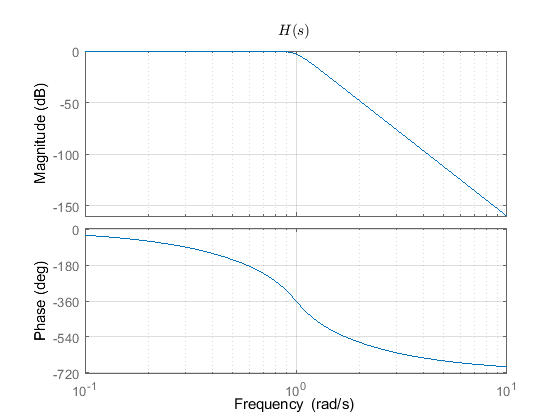

fig0=figure; bode(sysS); ...
title(sprintf('$$%s$$', 'H(s)'), 'Interpreter','latex'); grid on;...
saveas(fig0,'output/stm32_iir_hp_butterworth_0','jpg');

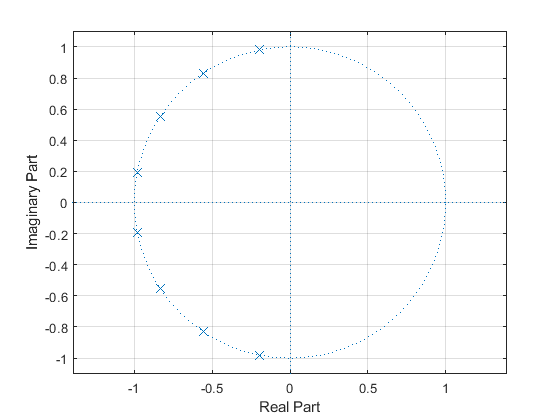

fig1=figure; Np=max(length(BS),length(AS));
zplane( [zeros(1, Np-length(BS)) BS], [  zeros(1, Np-length(AS)) AS] );...
grid on; saveas(fig1,'output/stm32_iir_hp_butterworth_1','jpg');

syms s; ecu_latex = ['H(s)=', latex(poly2sym(BS,s)/poly2sym(AS,s))];
save_ecu('output/stm32_iir_hp_butterworth_ecu_SM.tex', ecu_latex);

- Transformación en frecuencia final de pasa bajo normalizado a paso alto

[Bs, As] = mi_lp2hp(BS, AS, 2*pi*fc);
syss=tf(Bs,As)

syss =
 
                                                            
                                                4.504e15 s^8
                                                            
  --------------------------------------------------------------------------------------------------------
                                                                                                          
  4.505e15 s^8 + 1.451e20 s^7 + 2.336e24 s^6 + 2.441e28 s^5 + 1.803e32 s^4 + 9.636e35 s^3 + 3.641e39 s^2  
                                                                                                          
                                                                                   + 8.925e42 s + 1.094e46
                                                                                                          
 
Continuous-time transfer function.



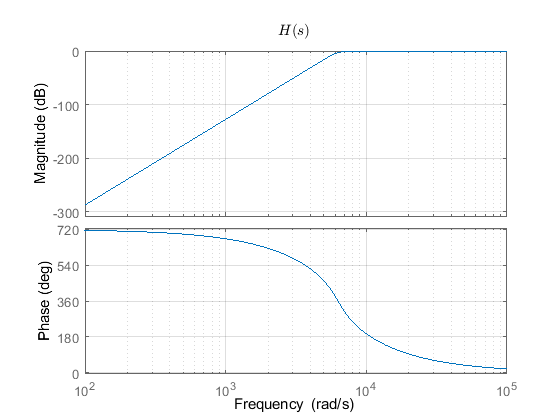

fig2=figure; bode(syss); ...
title(sprintf('$$%s$$', 'H(s)'), 'Interpreter','latex'); grid on;   ...
saveas(fig2,'output/stm32_iir_hp_butterworth_2','jpg');

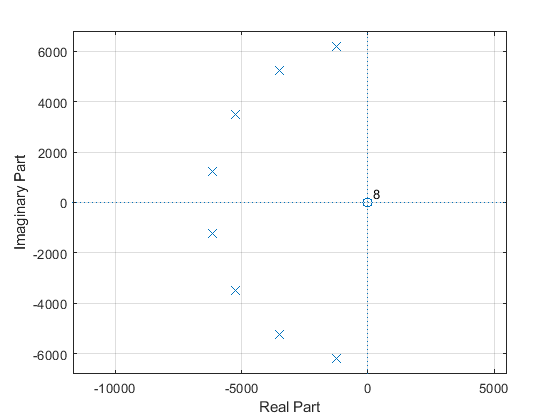


fig3=figure; Np=max(length(Bs),length(As));
zplane( [zeros(1, Np- length(Bs)) Bs  ], [zeros(1, Np- length(As))  As ] ); ...
grid on; saveas(fig3,'output/stm32_iir_hp_butterworth_3','jpg');

syms s; ecu_latex = ['H(s)=', latex(poly2sym(Bs,s)/poly2sym(As,s))];
save_ecu('output/stm32_iir_hp_butterworth_ecu_s.tex', ecu_latex);

**Transformación bilinear - matlab.**

mapeo="bilineal(matlab)";

switch mapeo
    case "integración"
        [Bz, Az]=mi_integral(Bs, As, fm);
    case "invariante al impulso"
        [Bz, Az]=mi_impinvar(Bs, As, fm);
    case "invariante(matlab)"
        [Bz, Az]=impinvar(Bs, As, fm);
    case "bilineal"
        [Bz, Az]=mi_bilinear(Bs, As, fm, fs);
    case "bilineal(matlab)"
        [Bz, Az]=bilinear(Bs, As, fm);        
end
Bz=Bz/Az(1);
Az=Az/Az(1);
sysz=tf(Bz,Az,1/fm,'Variable','z^-1')

sysz =
 
                                                                                                           
   0.4883 - 3.906 z^-1 + 13.67 z^-2 - 27.34 z^-3 + 34.18 z^-4 - 27.34 z^-5 + 13.67 z^-6 - 3.906 z^-7       
                                                                                                           
                                                                                              + 0.4883 z^-8
                                                                                                           
  ----------------------------------------------------------------------------------------------------------
                                                                                                            
  1 - 6.573 z^-1 + 19.01 z^-2 - 31.58 z^-3 + 32.95 z^-4 - 22.11 z^-5 + 9.308 z^-6 - 2.248 z^-7 + 0.2385 z^-8
                                                                                                            
               

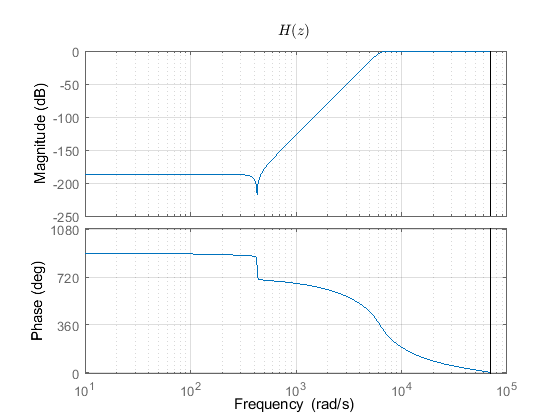

syms z; fig4=figure; bode(sysz); grid on;...
title(sprintf('$$%s$$', 'H(z)'), 'Interpreter','latex');    ...
saveas(fig4, 'output/stm32_iir_hp_butterworth_4', 'jpg');

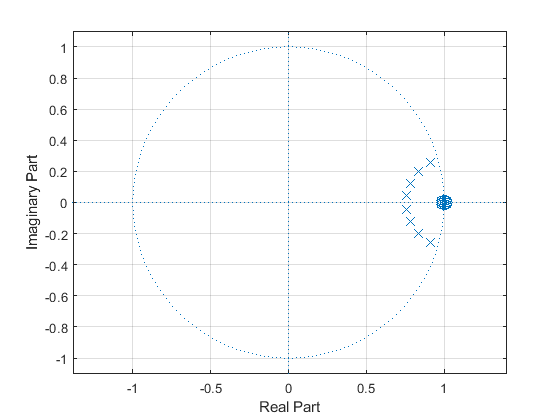

fig5=figure; Np=max( length(Bz),length(Az) );
zplane( [  zeros(1, Np- length(Bz)) Bz], [ zeros(1, Np- length(Az)) Az ] );...
grid on; saveas(fig5,'output/stm32_iir_hp_butterworth_5','jpg');

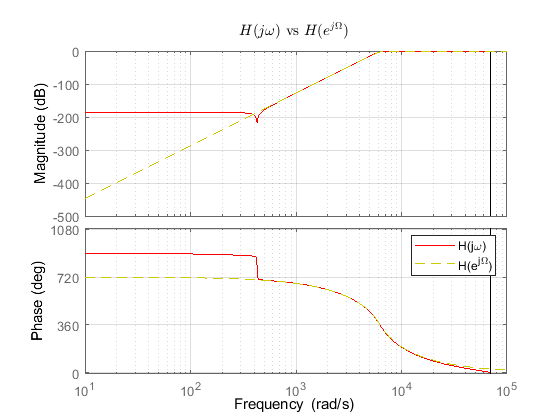


ecu_latex = ['H(z)=', latex(poly2sym(Bz,z)/poly2sym(Az,z))];
save_ecu('output/stm32_iir_hp_butterworth_ecu_z.tex', ecu_latex);

syms z; fig6=figure; bode(sysz,'r',syss,'y--'); grid on;...
title(sprintf('$$%s$$', 'H(j\omega)\mbox{ vs }H(e^{j\Omega})'), 'Interpreter','latex');    ...    
legend( sprintf('%s', 'H(j\omega)'), sprintf('%s', 'H(e^{j\Omega})'));   
saveas(fig6,'output/stm32_iir_hp_butterworth_6','jpg');

**Generación de la linea de código para el micrcontrolador - **vector de coeficientes

PRECISION_STM32=8;
stm32_coef=to_stm32(Bz, Az, N, fm, PRECISION_STM32, 'IIR - Buttherworth - Pasa Alto', mapeo); ...
saveImplementacion('output/stm32_iir_hp_butterworth_stm32_coef.txt', stm32_coef);...
fprintf('%s\n',stm32_coef) 

//Filtro IIR - Buttherworth - Pasa Alto - bilineal(matlab) 
//Orden: 8
//Frecuencia de Muestreo: 22418 (Hz)
#define ORDEN 8
double coef_x[]= {0.48826428,-3.90611423,13.67139981,-27.34279962,34.17849952, 
			-27.34279962,13.67139981,-3.90611423,0.48826428};
double coef_y[]= {-1.00000000,6.57317134,-19.01078560,31.58375452,-32.95474459, 
			22.10645539,-9.30768750,2.24831447,-0.23849661};


**Generación de la linea para inicializar el callback de simulink**

simulink_coef=to_simulink(Bz, Az, N, fm, PRECISION_STM32, 'IIR - Butterworth - Pasa Alto', mapeo); ...
saveImplementacion('output/stm32_iir_hp_butterworth_simulink_coef.txt', simulink_coef); ...
fprintf('%s\n',simulink_coef) 

	%Filtro IIR - Butterworth - Pasa Alto - bilineal(matlab) 
	%Orden: 8
	%Frecuencia de Muestreo: 22418 (Hz)
	Fm=22418;
	ORDEN=8;
	coef_x= [0.48826428,-3.9061142,13.6714,-27.3428,34.1785, ...
			-27.3428,13.6714,-3.9061142,0.48826428];
	coef_y= [-1,6.5731713,-19.010786,31.583755,-32.954745, ...
			22.106455,-9.3076875,2.2483145,-0.23849661];



save('output/stm32_iir_hp_butterworth.mat');